直進動作

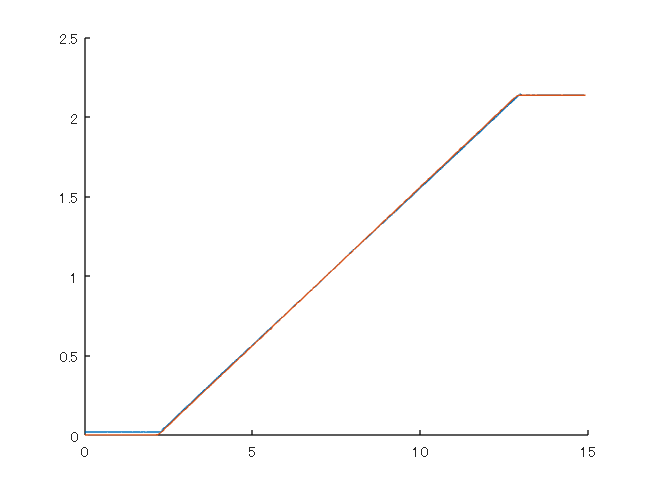

clear;

roomba_csv = readmatrix("forward_odometry_data.csv");
capture_csv = readmatrix("forward_motion_caputured_data.csv");

capture.time = capture_csv(:,1) - capture_csv(1,1);
capture.x = capture_csv(:,2);
capture.y = capture_csv(:,3) - capture_csv(1,3);
capture.theta = capture_csv(:,4);

roomba.time = roomba_csv(:,1)/1000 - roomba_csv(1,1)/1000;
roomba.x = roomba_csv(:,2);
roomba.y = roomba_csv(:,3);
roomba.theta = roomba_csv(:,4);

figure; hold on;
plot(capture.time,capture.x);
plot(roomba.time,roomba.x);

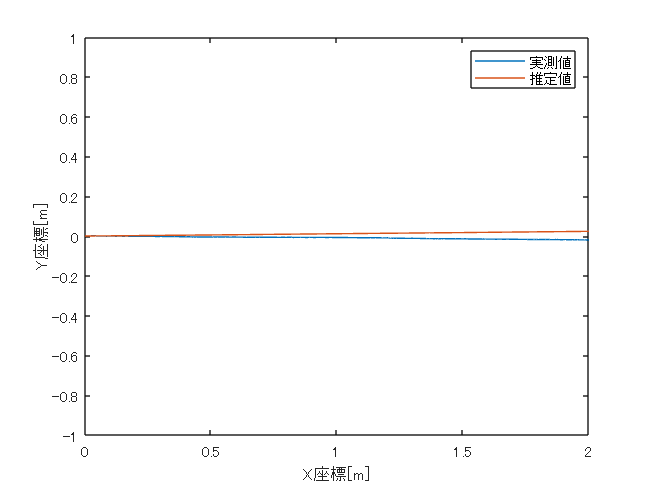


figure;
hold on;
box on;
plot(capture.x,capture.y);
plot(roomba.x, roomba.y);
xlim([0 2]);
ylim([-1 1]);
legend('実測値','推定値');
xlabel('X座標[m]');
ylabel('Y座標[m]');
saveas(gcf, '../graphs/forward_odo_graph','epsc');

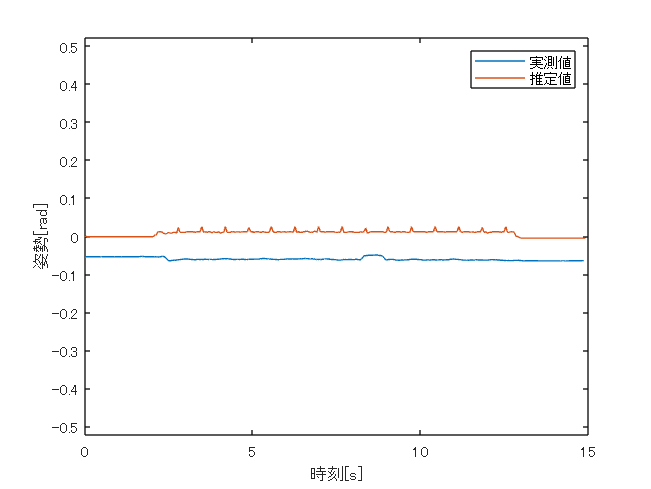


figure;
hold on;
box on;
plot(capture.time, capture.theta);
plot(roomba.time, roomba.theta);
legend('実測値','推定値');
xlabel('時刻[s]');
ylabel('姿勢[rad]');
ylim([-pi/6 pi/6]);
saveas(gcf, '../graphs/forward_pose_graph','epsc');

その場旋回

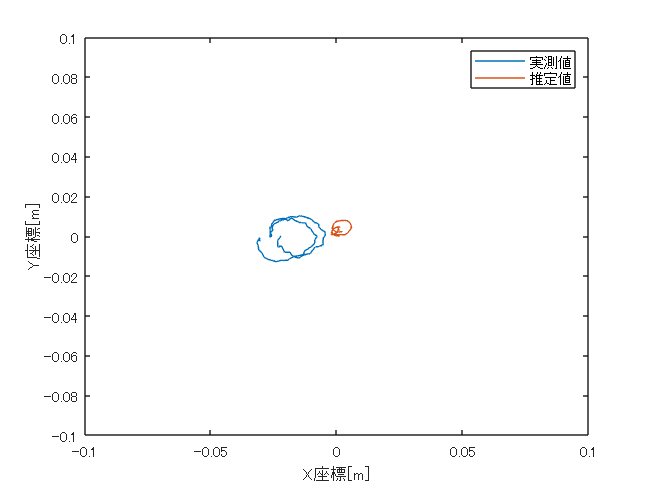

clear;
roomba_csv = readmatrix("rotation_odometry_data.csv");
capture_csv = readmatrix("rotation_motion_caputured_data.csv");

capture.time = capture_csv(:,1) - capture_csv(1,1);
capture.x = capture_csv(:,2);
capture.y = capture_csv(:,3) - capture_csv(1,3);
capture.theta = capture_csv(:,4);

roomba.time = roomba_csv(:,1)/1000 - roomba_csv(1,1)/1000;
roomba.x = roomba_csv(:,2);
roomba.y = roomba_csv(:,3);
roomba.theta = roomba_csv(:,4);

figure;
hold on;
box on;
plot(capture.x,capture.y);
plot(roomba.x, roomba.y);
xlim([-0.1 0.1]);
ylim([-0.1 0.1]);
legend('実測値','推定値');
xlabel('X座標[m]');
ylabel('Y座標[m]');
saveas(gcf, '../graphs/rotation_odo_graph','epsc');

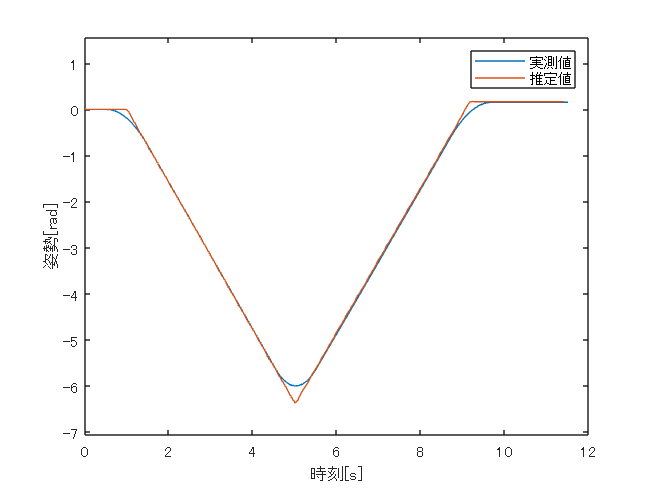


figure;
hold on;
box on;
plot(capture.time, capture.theta);
plot(roomba.time, roomba.theta);
legend('実測値','推定値');
xlabel('時刻[s]');
ylabel('姿勢[rad]');
ylim([-9/4*pi pi/2]);
saveas(gcf, '../graphs/rotation_pose_graph','epsc');

定常円動作

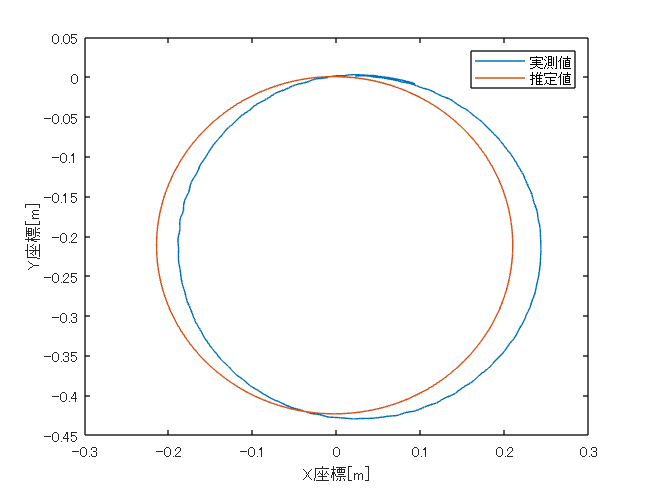

clear;
roomba_csv = readmatrix("circle_odometry_data.csv");
capture_csv = readmatrix("circle_motion_caputured_data.csv");

capture.time = capture_csv(:,1) - capture_csv(1,1);
capture.x = capture_csv(:,2);
capture.y = capture_csv(:,3);
capture.theta = capture_csv(:,4);

roomba.time = roomba_csv(:,1)/1000 - roomba_csv(1,1)/1000;
roomba.x = roomba_csv(:,2);
roomba.y = roomba_csv(:,3);
roomba.theta = roomba_csv(:,4);

figure;
hold on;
box on;
plot(capture.x,capture.y);
plot(roomba.x, roomba.y);
% xlim([-0.1 0.1]);
% ylim([-0.1 0.1]);
legend('実測値','推定値');
xlabel('X座標[m]');
ylabel('Y座標[m]');
saveas(gcf, '../graphs/circle_odo_graph','epsc');

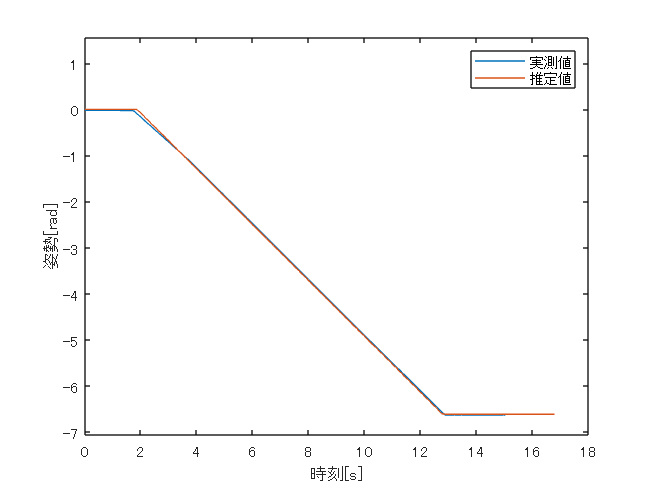


figure;
hold on;
box on;
plot(capture.time, capture.theta);
plot(roomba.time, roomba.theta);
legend('実測値','推定値');
xlabel('時刻[s]');
ylabel('姿勢[rad]');
ylim([-9/4*pi pi/2]);
saveas(gcf, '../graphs/circle_pose_graph','epsc');

長方形動作

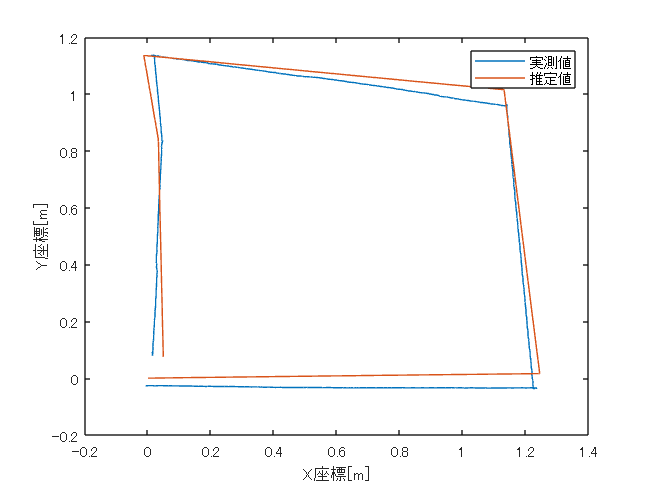

clear;
roomba_csv = readmatrix("rectangle_odometry_data.csv");
capture_csv = readmatrix("rectangle_motion_caputured_data.csv");

capture.time = capture_csv(:,1) - capture_csv(1,1);
capture.x = capture_csv(:,2);
capture.y = capture_csv(:,3);
capture.theta = capture_csv(:,4);

roomba.time = roomba_csv(:,1)/1000 - roomba_csv(1,1)/1000;
roomba.x = roomba_csv(:,2);
roomba.y = roomba_csv(:,3);
roomba.theta = roomba_csv(:,4);

figure;
hold on;
box on;
plot(capture.x,capture.y);
plot(roomba.x, roomba.y);
% xlim([-0.1 0.1]);
% ylim([-0.1 0.1]);
legend('実測値','推定値');
xlabel('X座標[m]');
ylabel('Y座標[m]');
saveas(gcf, '../graphs/rectangle_odo_graph','epsc');

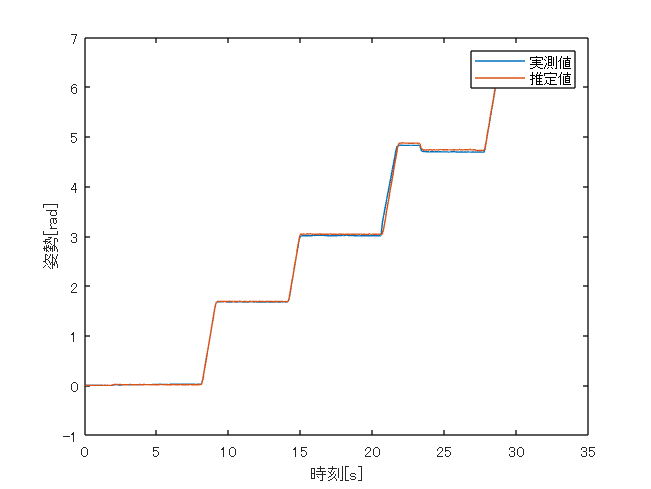


figure;
hold on;
box on;
plot(capture.time, capture.theta);
plot(roomba.time, roomba.theta);
legend('実測値','推定値');
xlabel('時刻[s]');
ylabel('姿勢[rad]');
% ylim([-9/4*pi pi/2]);
saveas(gcf, '../graphs/rectangle_pose_graph','epsc');